# Quickstart: Accessing Neuropixels Electrophysiology Data from the Allen Brain Observatory

This example demonstrates quick access and basic analysis of the Visual Coding Neuropixels dataset [1] from the Allen Brain Observatory [2].

### Accessing the Visual Coding Neuropixels Dataset

availSessions = bot.fetchSessions('ephys');

To access probes, channels or units instead of sessions, use `bot.fetchProbes()`, `bot.fetchChannels(),` and `bot.fetchUnits()` respectively.

### Examining Sessions

#### Inspecting Available Sessions 

head(availSessions)

ans = 8×15 table
       id        unit_count    channel_count    probe_count        session_type         age_in_days    fail_eye_tracking    sex                      full_genotype                                                                      ephys_structure_acronyms                                                    isi_experiment_id    date_of_acquisition     specimen_id      specimen      well_known_files
    _________    __________    _____________    ___________    _____________________    ___________    _________________    ___    _________________________________________________

#### Selecting Sessions of Interest

% select sessions with female subjects
filteredSessions = availSessions(availSessions.sex == "F",:);

% select sessions with wild-type subjects
filteredSessions = filteredSessions(filteredSessions.full_genotype == "wt/wt",:);

% select sessions designed to investigate functional connectivity
filteredSessions = filteredSessions(filteredSessions.session_type == "functional_connectivity",:); 
disp(filteredSessions)

       id        unit_count    channel_count    probe_count         session_type          age_in_days    fail_eye_tracking    sex    full_genotype                                              ephys_structure_acronyms                                              isi_experiment_id    date_of_acquisition     specimen_id      specimen      well_known_files
    _________    __________    _____________    ___________    _______________________    ___________    _________________    ___    _____________    _______________________________________________________________________________

#### Creating Session Objects

% sort sessions from most number of units to least
sortedSessions = sortrows(filteredSessions, 'unit_count', 'descend');
sessionUnderStudy = bot.session(sortedSessions(1, :));
sessionUnderStudy.info

ans = struct with fields:
                          id: 847657808
                  unit_count: 874
               channel_count: 2298
                 probe_count: 6
                session_type: functional_connectivity
                 age_in_days: 126
           fail_eye_tracking: 0
                         sex: F
               full_genotype: "wt/wt"
    ephys_structure_acronyms: "APN; CA1; CA3; DG; HPF; LP; MB; MGd; NOT; POST; ProS; SGN; SUB; TH; VISal; VISam; VISl; VISp; VISpm; VISrl"
           isi_experiment_id: 836962226
         date_of_acquisition: 08-Apr-2019 19:30:50
                 specimen_id: 827809884
                    specimen: [1×1 struct]
            well_known_files: [1×1 struct]


#### Inspecting Session Object Properties

disp(sessionUnderStudy)

  EphysSession with properties:

                              info: [1×1 struct]
                                id: 847657808
                       linkedFiles: [2×1 table]

   Info Derived Values
                structure_acronyms: [1×20 string]

   Linked Items
                            probes: [6×23 table]
                          channels: [2298×29 table]
                             units: [874×51 table]

   Linked Item Derived Values


       channel_structure_intervals: [43×2 table]
         structurewise_unit_counts: [16×2 table]

   Linked File Values ('SessNWB')
      inter_presentation_intervals: '[on demand]'
                     invalid_times: '[on demand]'
                    mean_waveforms: '[on demand]'
    optogenetic_stimulation_epochs: '[on demand]'
                        pupil_data: '[on demand]'
               pupil_data_detailed: '[on demand]'
                      rig_metadata: '[on demand]'
                     running_speed: '[on demand]'
                session_start_time: '[on demand]'
                  spike_amplitudes: '[on demand]'
                       spike_times: '[on demand]'
               stimulus_conditions: '[on demand]'
                   stimulus_epochs: '[on demand]'
                    stimulus_names: '[on demand]'
            stimulus_presentations: '[on demand]'

   Linked File Values ('StimTemplatesGroup')
                stimulus_templates: '[on demand]'



### Group Analysis of Session Units

unitsTable = sessionUnderStudy.units;
head(unitsTable)

ans = 8×51 table
       id        ephys_channel_id    ephys_probe_id    ephys_session_id         session_type          ephys_structure_acronym     L_ratio      age_in_days    air_channel_index    amplitude_cutoff    anterior_posterior_ccf_coordinate    cumulative_drift    d_prime    dorsal_ventral_ccf_coordinate    fail_eye_tracking    firing_rate    has_lfp_data    isi_violations    isolation_distance    left_right_ccf_coordinate    lfp_temporal_subsampling_factor    max_drift    nn_hit_rate    nn_miss_rate    peak_channel    presence_ratio    

summary(unitsTable(:,"firing_rate"));

Description:  epoch_name_quality_metrics: complete_session - epoch_name_waveform_metrics: complete_session - quality: good - type: EPhys - published_at: 03-Oct-2019 - has_nwb: true 

Variables:

    firing_rate: 874×1 double

        Values:

            Min       0.12266 
            Median     4.9347 
            Max        57.265 



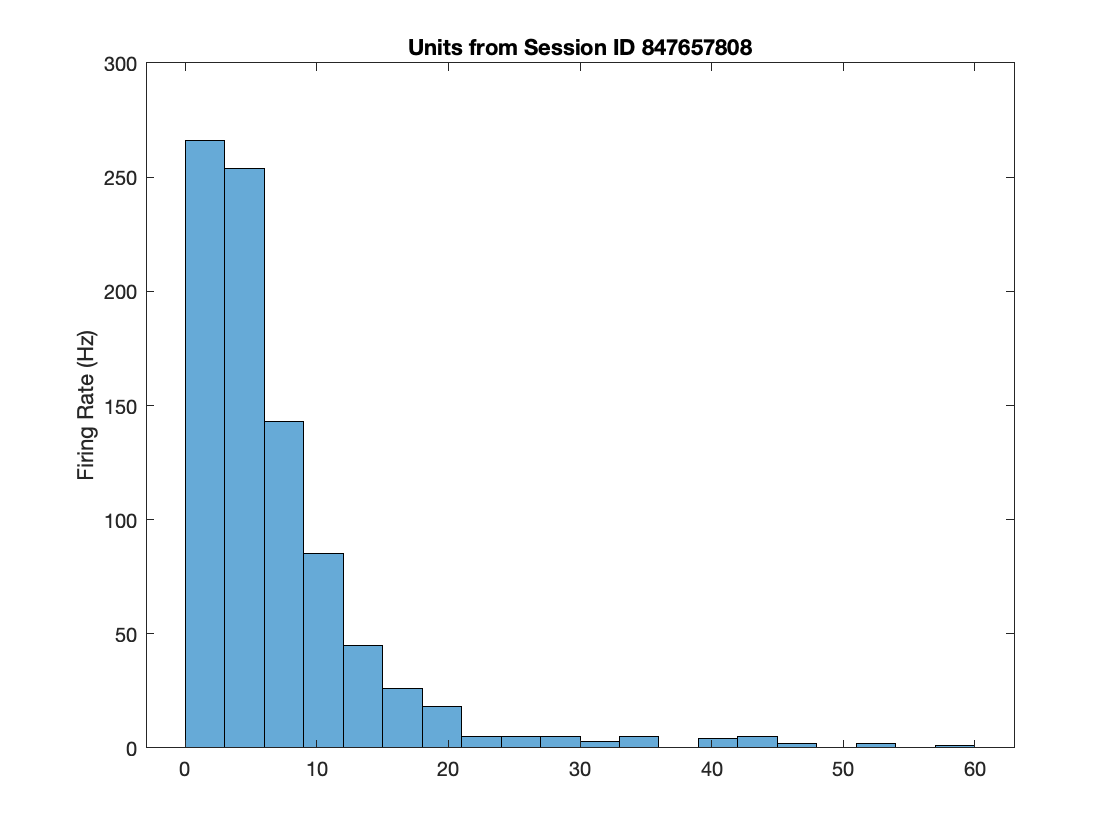

histogram(unitsTable.firing_rate);
ylabel('Firing Rate (Hz)');
title("Units from Session ID " + sessionUnderStudy.id);

### Examining Probes

probes = sessionUnderStudy.probes;

% obtain a `probe` object for the first probe
probe = bot.probe(probes(1, :))

probe =   Probe with properties:

           info: [1×1 struct]
             id: 848037568
    linkedFiles: [1×1 table]

   Linked Items
        session: [1×1 bot.item.concrete.EphysSession]
       channels: [383×29 table]
          units: [248×51 table]

   Linked File Values ('LFPNWB')
        lfpData: '[on demand]'
        csdData: '[on demand]'


disp(fieldnames(probe.info))

    {'id'                             }
    {'ephys_session_id'               }
    {'unit_count'                     }
    {'channel_count'                  }
    {'name'                           }
    {'session_type'                   }
    {'age_in_days'                    }
    {'air_channel_index'              }
    {'fail_eye_tracking'              }
    {'has_lfp_data'                   }
    {'lfp_sampling_rate'              }
    {'lfp_temporal_subsampling_factor'}
    {'phase'                          }
    {'sampling_rate'                  }
    {'sex'                            }
    {'surface_channel_index'          }
    {'genotype'                       }
    {'ephys_structure_acronyms'       }
    {'isi_experiment_id'              }
    {'date_of_acquisition'            }
    {'specimen_id'                    }
    {'specimen'                       }
    {'well_known_files'               }



#### Probe Low Frequency Data

head(probe.lfpData)

ans = 8×1 timetable
       Time       LocalFieldPotential
    __________    ___________________

    4.138 sec        [1×92 single]   
    4.1388 sec       [1×92 single]   
    4.1396 sec       [1×92 single]   
    4.1404 sec       [1×92 single]   
    4.1412 sec       [1×92 single]   
    4.142 sec        [1×92 single]   
    4.1428 sec       [1×92 single]   
    4.1436 sec       [1×92 single]   


probe.csdData

ans = struct with fields:
                   data: [876×1 timetable]
    horizontalPositions: [384×1 double]
      verticalPositions: [384×1 double]


### Examining Channels

channels = sessionUnderStudy.channels;

% obtain a `channel` object for the first channel
channel = bot.channel(channels(1, :))

channel =   Channel with properties:

       info: [1×1 struct]
         id: 867380169

   Linked Items
    session: [1×1 bot.item.concrete.EphysSession]
      probe: [1×1 bot.item.Probe]
      units: [0×51 table]


disp(fieldnames(channel.info))

    {'id'                               }
    {'ephys_probe_id'                   }
    {'ephys_session_id'                 }
    {'unit_count'                       }
    {'session_type'                     }
    {'ephys_structure_acronym'          }
    {'age_in_days'                      }
    {'air_channel_index'                }
    {'anterior_posterior_ccf_coordinate'}
    {'dorsal_ventral_ccf_coordinate'    }
    {'fail_eye_tracking'                }
    {'has_lfp_data'                     }
    {'left_right_ccf_coordinate'        }
    {'lfp_sampling_rate'                }
    {'lfp_temporal_subsampling_factor'  }
    {'local_index'                      }
    {'phase'                            }
    {'probe_horizontal_position'        }
    {'probe_name'                       }
    {'probe_vertical_position'          }
    {'sampling_rate'                    }
    {'sex'                              }
    {'surface_channel_index'            }
    {'genotype'                   

### Examining Units

units = sessionUnderStudy.units;

% filter for units in the VISam area
units = units(units.ephys_structure_acronym == 'VISam', :)

units = 65×51 table
       id        ephys_channel_id    ephys_probe_id    ephys_session_id         session_type          ephys_structure_acronym     L_ratio     age_in_days    air_channel_index    amplitude_cutoff    anterior_posterior_ccf_coordinate    cumulative_drift    d_prime    dorsal_ventral_ccf_coordinate    fail_eye_tracking    firing_rate    has_lfp_data    isi_violations    isolation_distance    left_right_ccf_coordinate    lfp_temporal_subsampling_factor    max_drift    nn_hit_rate    nn_miss_rate    peak_channel    presence_ratio    

% obtain a `unit` object for the first unit
unit = bot.unit(units(1, :))

unit =   Unit with properties:

       info: [1×1 struct]
         id: 951185413

   Linked Items
    session: [1×1 bot.item.concrete.EphysSession]
    channel: [1×1 bot.item.Channel]
      probe: [1×1 bot.item.Probe]


disp(fieldnames(unit.info))

    {'id'                               }
    {'ephys_channel_id'                 }
    {'ephys_probe_id'                   }
    {'ephys_session_id'                 }
    {'session_type'                     }
    {'ephys_structure_acronym'          }
    {'L_ratio'                          }
    {'age_in_days'                      }
    {'air_channel_index'                }
    {'amplitude_cutoff'                 }
    {'anterior_posterior_ccf_coordinate'}
    {'cumulative_drift'                 }
    {'d_prime'                          }
    {'dorsal_ventral_ccf_coordinate'    }
    {'fail_eye_tracking'                }
    {'firing_rate'                      }
    {'has_lfp_data'                     }
    {'isi_violations'                   }
    {'isolation_distance'               }
    {'left_right_ccf_coordinate'        }
    {'lfp_temporal_subsampling_factor'  }
    {'max_drift'                        }
    {'nn_hit_rate'                      }
    {'nn_miss_rate'               

### References

[1] Copyright 2019 Allen Institute for Brain Science. Visual Coding Neuropixels. Available from: [portal.brain-map.org/explore/circuits/visual-coding-neuropixels](https://portal.brain-map.org/explore/circuits/visual-coding-neuropixels).

[2] Copyright 2016 Allen Institute for Brain Science. Allen Brain Observatory. Available from: [portal.brain-map.org/explore/circuits](http://portal.brain-map.org/explore/circuits). 